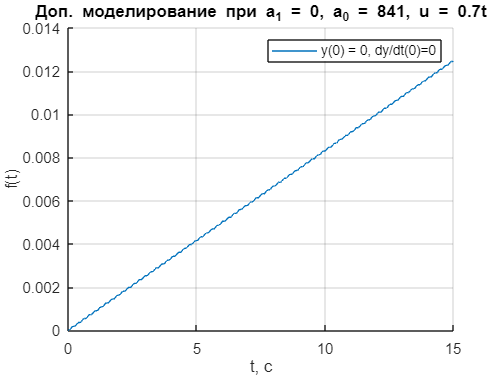

open_system('scheme_1');
set_param('scheme_1/y1', 'VariableName', 'y1')
set_param('scheme_1/y2', 'VariableName', 'y2')
set_param('scheme_1/y3', 'VariableName', 'y3')
set_param('scheme_1/y4', 'VariableName', 'y4')

out = sim('scheme_1');

%plot(out.y1,'-', 'LineWidth',0.1, 'DisplayName', 'y(0) = -1, dy/dt(0)=0')
hold on
plot(out.y2,'-', 'LineWidth',0.1, 'DisplayName', 'y(0) = 0, dy/dt(0)=0')

%plot(out.y3, ':','LineWidth',0.1, 'DisplayName', 'y(0) = 1, dy/dt(0)=0')
%plot(out.y4, '-','LineWidth',2, 'DisplayName', 'y(0) = 1, dy/dt(0)=0')

grid()
%title('Моделирование при a_1 = 7.4, a_0 = 38.69, u = cos(4t)')
%title('Моделирование при a_1 = 0, a_0 = 841, u = cos(4t)')
title('Доп. моделирование при a_1 = 0, a_0 = 841, u = 0.7t')
legend
ylabel('f(t)')
xlabel('t, с')
hold off